clear;clc;

% load parameters
par_scg = importdata('par_scg_clock.txt');
par_scg = par_scg.data;

par_clock = load('par_clock.csv');
n_clock = 12;

% initial values
y0 = zeros(n_clock+7, 1);
y0(n_clock+1) = 1;
y0(n_clock+4) = 100;

tmax = 1000;
tspan = 0:0.1:tmax;

y = zeros(length(tspan), n_clock+7, 2);
t_V_17 = 523; % from paper CT17 is the acrophase of Bmal1
t_V_6 = 512;

[~, y(:, :, 1)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_6);
[~, y(:, :, 2)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_17);
y = real(y);

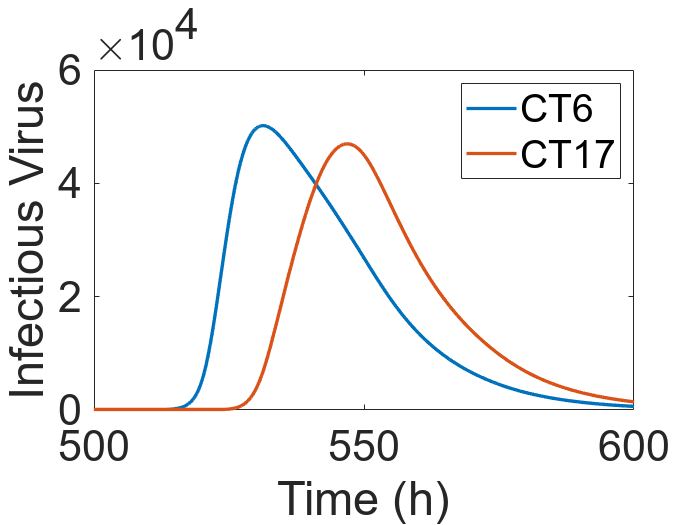

% Plot virus 
figure; hold on; set(gca,'Fontsize',26); box on;
for i = 1:2
    plot(tspan, y(:, n_clock+4, i), 'LineWidth', 2);
end
xlim([500 600]);
xlabel('Time (h)'); ylabel('Infectious Virus');
legend('CT6', 'CT17');
hold off;

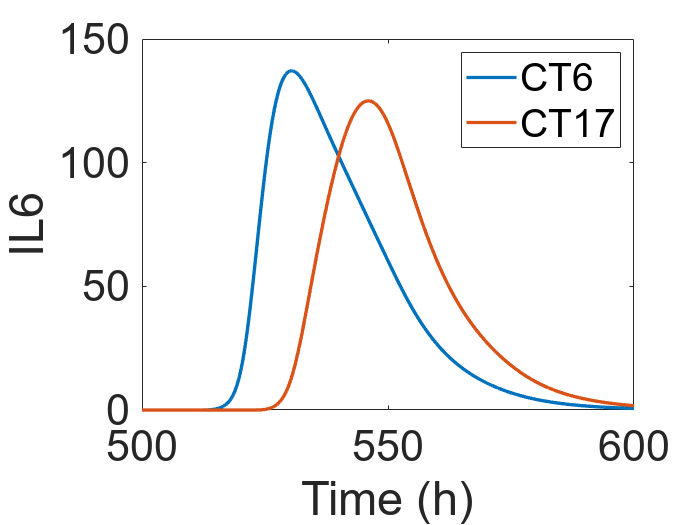

% Plot cytokines
figure; hold on; set(gca,'Fontsize',26); box on;
for i = 1:2
    plot(tspan, y(:, n_clock+5, i), 'LineWidth', 2);
end
xlim([500 600]);
xlabel('Time (h)'); ylabel('IL6');
legend('CT6', 'CT17');
hold off;

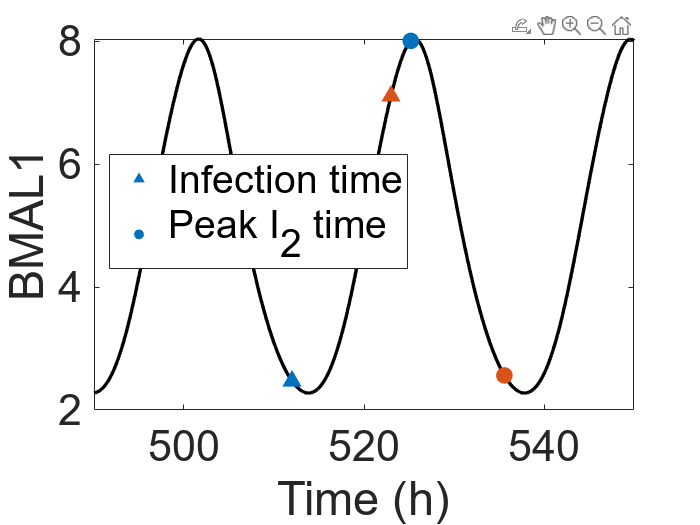

% Plot BMAL1/REV and phases of infection and peak time of I2
peak_idx_I2 = zeros(2, 1);    
for i = 1:2
    I2 = y(:, n_clock+3, i);
    [~, peak_idx_I2(i)] = max(I2);
end
% Plot BMAL1 and phases
figure; hold on; set(gca,'Fontsize',26); box on;
plot(tspan, y(:, 10, 1), 'k', 'LineWidth', 2);
sz = 100;
c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
scatter([t_V_6, t_V_17], [y(t_V_6 .* 10 + 1, 10, 1), y(t_V_17 .* 10 + 1, 10, 1)], sz, c, '^', 'filled');
scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 10, 1),  sz, c, 'filled');
xlim([490 550]);
xlabel('Time (h)'); ylabel('BMAL1');
legend('', 'Infection time', 'Peak I_2 time');
hold off;

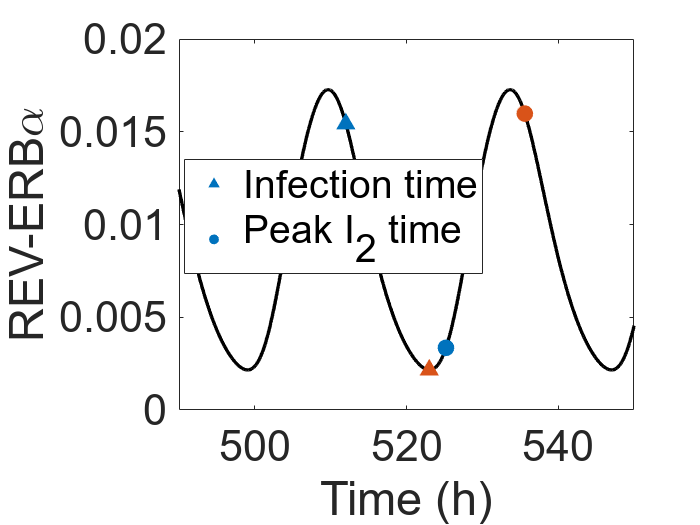

% Plot REV and phases
figure; hold on; set(gca,'Fontsize',26); box on;
plot(tspan, y(:, 8, 1), 'k', 'LineWidth', 2);
sz = 100;
c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
scatter([t_V_6, t_V_17], [y(t_V_6 .* 10 + 1, 8, 1), y(t_V_17 .* 10 + 1, 8, 1)], sz, c, '^', 'filled');
scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 8, 1),  sz, c, 'filled');
xlim([490 550]);
xlabel('Time (h)'); ylabel('REV-ERB\alpha');
legend('', 'Infection time', 'Peak I_2 time');
hold off;